clear all;
close all;

% Constants
vs = 34300; % Speed of sound (cm/s)
f = 2000

f = 2000

omega = f * 2 * pi; % Frequency (rad/s)

% Grid size (physical dimensions)
si = 50; % Size of grid in cm
grid_points = 150; % Number of grid points
x = linspace(-si/2, si/2, grid_points); % x-coordinates
y = linspace(0, si, grid_points); % y-coordinates
[X, Y] = meshgrid(x, y); % Create a 2D grid

% Source and microphone positions
mic_spacing = [1 2 3 4 5 6]

mic_spacing =      1     2     3     4     5     6


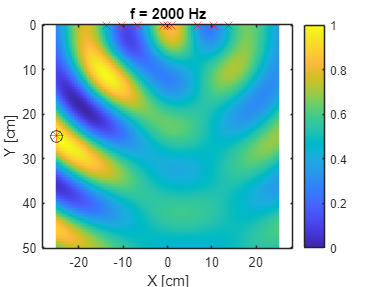

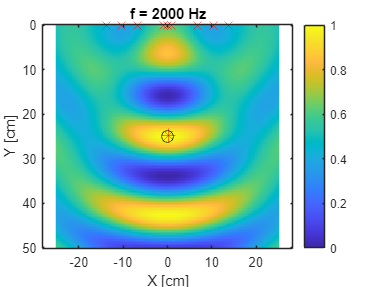

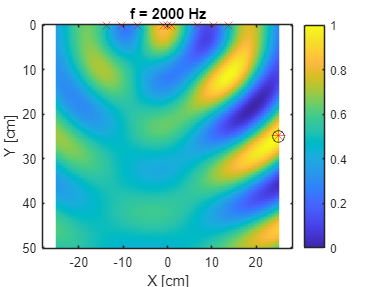

rn = [-13.72 0; -10.29 0; -6.86 0; -1 0; 0 0; 1 0; 6.86 0; 10.29 0;13.72 0]; % Microphone positions (cm)

% Initialize parameters for sweeping
focus_y = 25; % Fixed y-coordinate for the focus point
focus_x_range = linspace(-si/2, si/2, 3); % Sweep x-coordinate of focus point
num_sweeps = length(focus_x_range);

% Loop through each focus point and generate separate figures
for sweep_idx = 1:num_sweeps
    % Current focal point
    rf = [focus_x_range(sweep_idx), focus_y]; 

    % Initialize directivity matrix
    D = zeros(grid_points, grid_points);

    % Calculate directivity for the current focal point
    for n = 1:size(rn, 1)
        dist_focus_to_mic = vecnorm(rf - rn(n,:), 2, 2); % Focus to mic
        for i = 1:grid_points
            for j = 1:grid_points
                grid_point = [X(i, j), Y(i, j)];
                dist_point_to_mic = vecnorm(grid_point - rn(n,:), 2, 2); % Grid to mic
                D(i, j) = D(i, j) + exp(-1j * omega * dist_point_to_mic / vs) ...
                                    .* exp(1j * omega * dist_focus_to_mic / vs)./size(rn,1);
            end
        end
    end
    clims = [0 1];
    % Plot directivity before making real
  % figure;
  % imagesc(x, y, abs(D),clims); % Plot the magnitude of directivity
  % colormap('gray')
  % %imagesc(x, y, abs(D))
  % colorbar;
  % title(['Kierunkowość (Focus X: ', num2str(rf(1)), ' cm)']);
  % xlabel('X (cm)');
  % ylabel('Y (cm)');
  % axis equal;
  % hold on;
%
  % % Plot microphone positions
  % scatter(rn(:,1), rn(:,2), 75, 'rx'); % Microphones in red
%
  % % Plot focal point
  % scatter(rf(1), rf(2), 75, 'ko'); % Focal point in blue
  % file_name_complex = sprintf('directivity_complex_focus_x_%d.stl', rf(1));
  % %save_stl_mesh(X, Y, abs(D), file_name_complex);
  % % Make D real
  
  % % Save directivity after making real
  % file_name_real = sprintf('directivity_real_focus_x_%d.stl', rf(1));
  % %save_stl_mesh(X, Y, abs(D), file_name_real);
  % % Plot directivity after making real
    D = 1+real(D);
    D =D./2;
    D = abs(D);
    %D = 1 + real(D);
    %D = 20.*log10(D)
    %D = min(D,[],"all")+D
    figure;
    imagesc(x, y, D,clims); % Plot the magnitude of directivity
    %imagesc(x, y, abs(D))
    %colormap('gray')
    colorbar;
    title([sprintf("f = %d Hz",f)]);
    xlabel('X [cm]');
    ylabel('Y [cm]');
    axis equal;
    hold on;% Find the indices of the maximum value in D
    [max_value, max_idx] = max(D(:)); 

    % Convert the linear index to row and column indices
    [row, col] = ind2sub(size(D), max_idx);

    % Plot a red "X" at the location of the maximum value
    plot(X(row, col), Y(row, col), 'r*', 'MarkerSize', 10); % Red X marker

    % Plot microphone positions
    scatter(rn(:,1), rn(:,2), 75, 'rx'); % Microphones in red

    % Plot focal point
    scatter(rf(1), rf(2), 75, 'ko'); % Focal point in blue
end


% Function to save a mesh as an STL file

function save_stl_mesh(X, Y, Z, file_name)
    % Create the triangulation object
    tri = delaunay(X, Y);  % Perform Delaunay triangulation
    vertices = [X(:), Y(:), Z(:)];  % Create vertices matrix

    % Create the triangulation object
    triang = triangulation(tri, vertices);

    % Write the triangulation to an STL file
    stlwrite(triang,file_name);
end